## **Digital Communication Systems Laboratory**

## **Laboratory 02**

### **Section 01**

The initial parameters are usually defined at the beginning of the program.

%TUID 915614617
clc; clear;
A = 8;              % Signal amplitude
rb = 2000;          % Fundamental frequency of signal
Tb = 1 / rb;        % Period of signal
fs = 100 * rb;      % Sampling frequency
Ts = 1 / fs;        % Sampling period

### Section 02

#### **Baseband and Passband**

All signals has bandwidth, limited or unlimited.

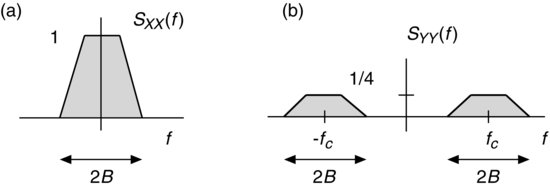

Bandpass: If a signal is band-limited and its spectrum center is around origin; Figure (a).

Passband: If a signal is band-limited and its spectrum center is far away from the origin; Figure (b).

*Hint*: the spectrum of all real valued signals is symetric regarded to the origin.

#### **Binary Coding**

Transmitting a message in any digital format needs a set of predefined symbols. For example, a text message needs alphanumeric, punctuation signs plus some other symbols to well describe the message content.

To transfer a message, a number or numerical index will be assigned to any symbol in the symbol set. These indices can be converted to binary format that is called binary codes.

For example in English language, we have 26 letters. If the symbol set only contains these alphabetic symbols, then we have indices from 0 to 25. How many bits is needed to be able to describe these 26 symbols:

0 bit                                1 symbols

1 bit                                2 symbols

2 bits                              4 symbols 

3 bits                              8 symbols

4 bits                              16 symbols

5 bits                               32 symbols

...                                    ...

$N_b$ bits                            $2^{N_b }$ symbols

Therefore, for 26 symbols, since 16 < 26 < 32, we have to select 5 bits (higher bound). The remaining capacity (32 - 26 = 6) will be wasted.

To prevent the capacity wastes, it is common to use all available symbols in binary coding. Hence, in most digital communication systems, the number of symbols is a power of two.

If there are M symbols in symbol set, at least $\left\lceil \mathrm{log2}\left(M\right)\right\rceil$ bits are needed to encode it in the binary format. $\left\lceil \ldotp \right\rceil$ shows the upper bound.

### Section 03

Suppose there are 2 symbols in the symbol set. Since there are just two symbols, they can be shown by 0 and 1.

M = 2;                  % Number of symbols
Nb = ceil(log2(M));     % Number of bits per symbol

Symbols can be generated randomly and then plotted as a pulse-shape signal:

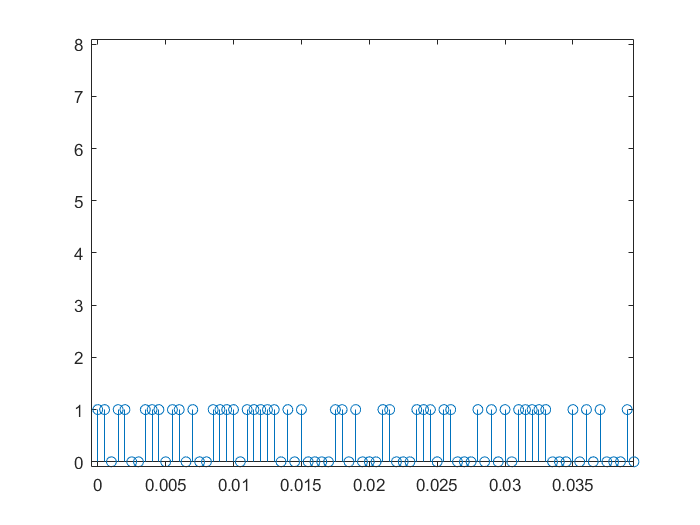

rng(0);                           % Reproducible random numbers
N = 80;    % Number of cycles
t = (0:N-1) * Tb;                   % Duration of cycles
binary = randi(M, [1, N]) - 1;    % Random bits
stem(t, binary); xlim([t(1)-t(2), t(end)+t(1)]); ylim([-0.1, A+0.1]);

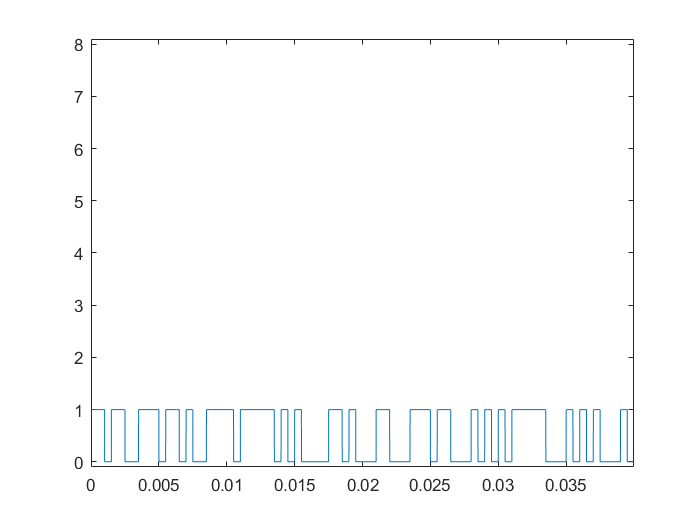

%% Increasing the number of samples
% t = 0:Ts:(N*Tb-Ts);                   % New sample time
% signal = binary(floor(t / Tb)+1);      % Change indices to new sampling frequency
signal = repelem(binary, floor(Tb/Ts));
t = (0:length(signal)-1)*Ts;
plot(t, signal); xlim([t(1)-t(2), t(end)+t(1)]); ylim([-0.1, A+0.1]);

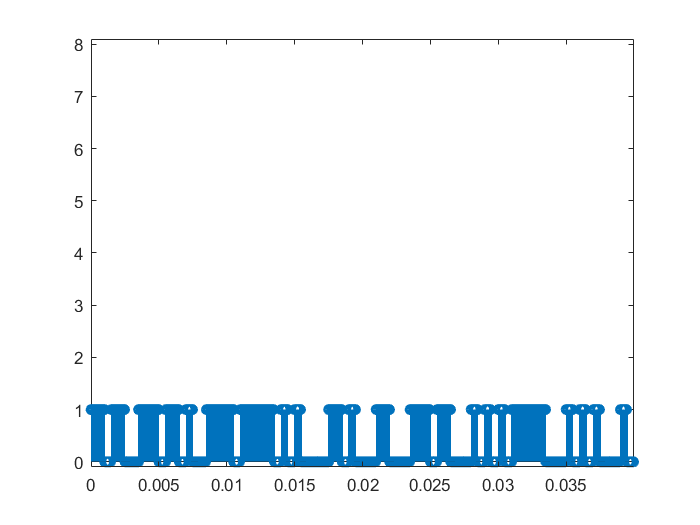

stem(t, signal); xlim([t(1)-t(2), t(end)+t(1)]); ylim([-0.1, A+0.1]);

### Section 04

#### Some Types of Binary Coding

Non-return-to-zero (NRZ): The pulse does not come back to zero for every cycle.

Return-to-zero(RZ): The pulse comes back to zero for a portion of cycle. This portion is usually a half.

Unipolar: A fixed positive value for symbol 1 and zero for symbol 0.

(Bi)Polar: A fixed positive value for symbols 1 and the negative of the same value for symbol 0.

Manchester: [1, -1] for symbol 1 and [-1, 1] for symbol 0.

Differential (Inverted): If the symbol is 0 the last pulse shape will be transmitted, but if the symbol is 1 the last pulse shape will be inverted.

#### Generating the Binary Codes

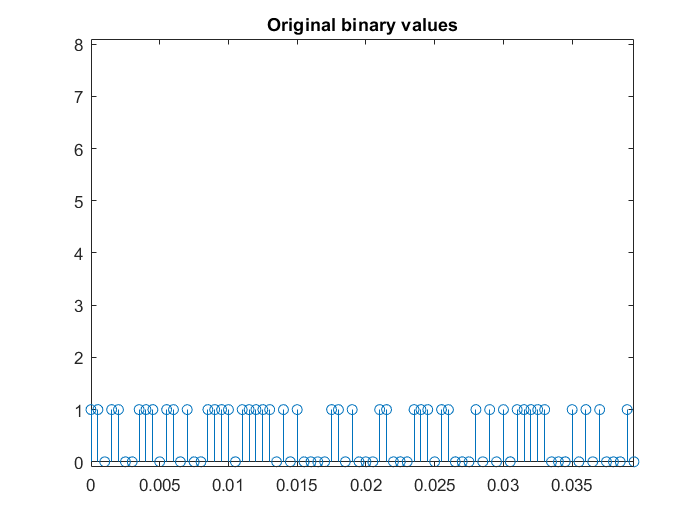

M = 2;                             % Number of symbols
Nb = ceil(log2(M));                % Number of bits per symbol
rng(0);                            % Reproducible random numbers
N = 80;      % Number of cycles
t = (0:(N-1)) * Tb;                  % Duration of cycles
binary = (randi(M, [1, N]) - 1); % Random bits
stem(t, binary); xlim([0, t(end)+t(1)]); ylim([-0.1, A+0.1]); title('Original binary values')

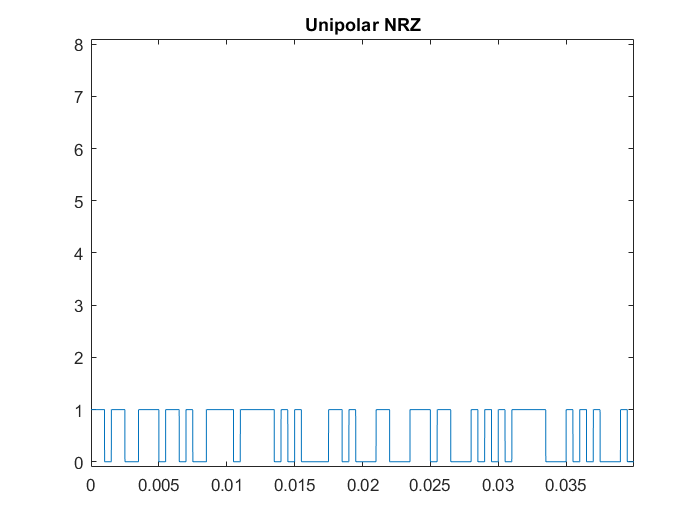

% Increasing the number of samples
signal = repelem(binary, floor(Tb/Ts));       % Change indices to the new sampling frequency
t = (0:length(signal)-1)*Ts;                  % New sample time
plot(t, signal); xlim([0, t(end)+t(1)]); ylim([-0.1, A+0.1]); title('Unipolar NRZ');

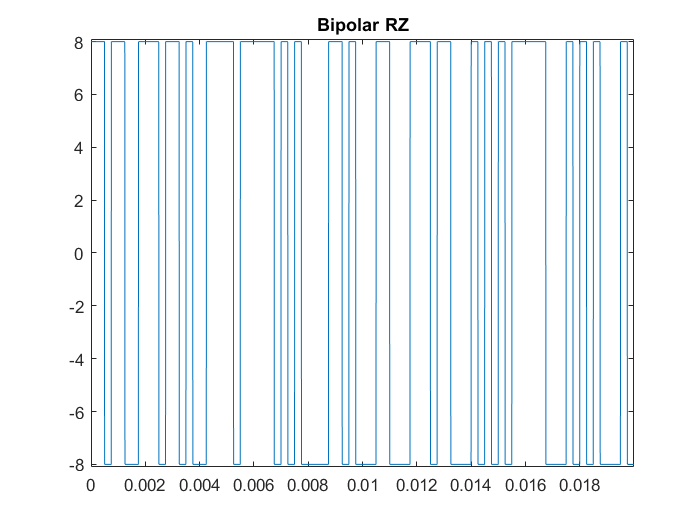

% Bipolar RZ
bnrz = 2 * (binary - 0.5);
signal_brz = A*repelem(bnrz, floor((Tb/2)/Ts));       % Change indices to the new sampling frequency
t=(0:length(signal_brz)-1)*Ts;
plot(t, signal_brz); xlim([0, t(end)+t(1)]); ylim([-A-0.1, A+0.1]); title('Bipolar RZ');


% Differential (Unipolar) NRZ
dunrz = zeros(size(binary));
dunrz(1) = binary(1);
for c = 2:length(binary)
    dunrz(c) = xor(dunrz(c-1), binary(c));
end
signal_dunrz = A*repelem(dunrz, floor(Tb/Ts));       % Change indices to the new sampling frequency
plot(t, signal_dunrz); xlim([0, t(end)+t(1)]); ylim([-0.1, A+0.1]); title('Differential Unipolar NRZ');

Error using plot
Vectors must be the same length.

% Unipolar Return to Zero (URZ)
urz = repelem(binary, 2);
urz(2:2:end) = 0;
% The RZ bit period is half of the NRZ
signal_urz = repelem(urz, floor((Tb/2)/Ts));    % Change indices to the new sampling frequency
plot(t, signal_urz); xlim([0, t(end)+t(1)]); ylim([-0.1, A+0.1]); title('Unipolar RZ');
% Manchester
manchester = repelem(binary, 2);
manchester_zeros = 0 * manchester(manchester == 0); manchester_zeros(1:2:end) = -1; manchester_zeros(2:2:end) = 1;
manchester_ones = 0 * manchester(manchester == 1); manchester_ones(1:2:end) = 1; manchester_ones(2:2:end) = -1;
man = manchester;
man(manchester == 0) = manchester_zeros;
man(manchester == 1) = manchester_ones;
signal_man = repelem(man, floor((Tb/2)/Ts));    % Change indices to the new sampling frequency
plot(t, signal_man); xlim([0, t(end)+t(1)]); ylim([-A-0.1, A+0.1]); title('Manchester');

### Section 05

#### Bandwidth of Binary Codings

Some binary codings need more bandwidth in comparison to others.

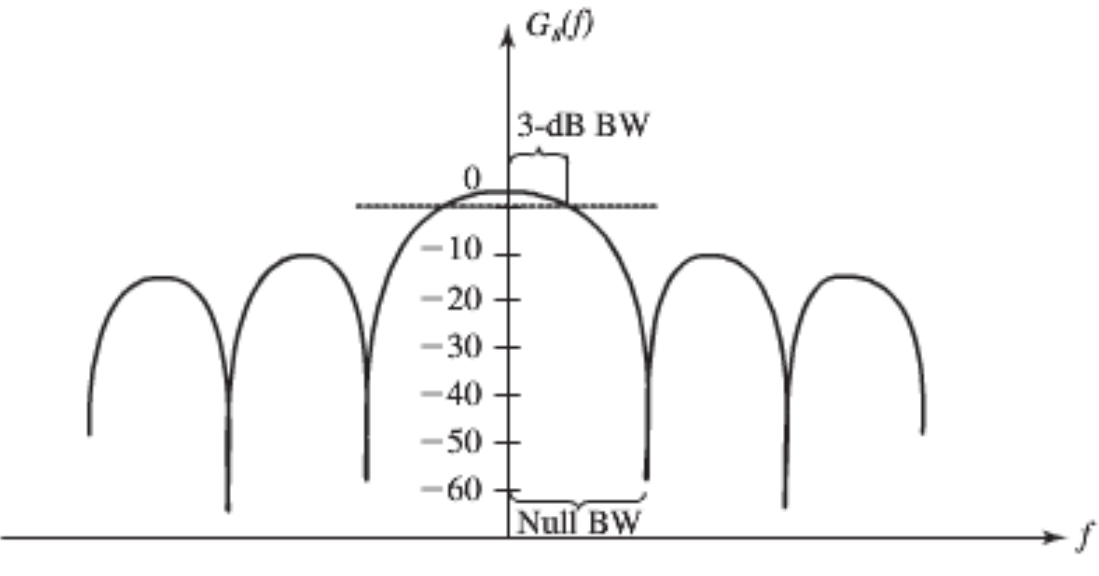

scope1 = dsp.SpectrumAnalyzer();
scope1.SampleRate = fs;
scope1.PlotAsTwoSidedSpectrum = false;
scope1.SpectrumUnits = "dBW";
scope1(signal_brz');
scope1.Name = 'Bipolar RZ';
release(scope1);

As it can be seen the Null BW of Unipolar NRZ is 1 KHz and equal to rb.

scope2 = dsp.SpectrumAnalyzer();
scope2.SampleRate = fs;
scope2.PlotAsTwoSidedSpectrum = false;
scope2.SpectrumUnits = "dBW";
scope2(signal_urz');
scope2.Name = "Unipolar RZ";
release(scope2);

This plot shows that the Null BW of Unipolar RZ is equal to 2 KHz and equal to 2rb.

It means that with the same symbol-rate (1KHz), the required bandwith of Unipolar RZ is twice as the Bipolar NRZ.

There are some other considerations such as power out of null bandwidth, error detection or corrections abilities that are beyond the scope of this laboratory.